This script is for simulation of FLP to decide the minimum photon count per second for a robust and reliable fluorescence lifetime photometry signal, based on the autofluorescence levels.

This is the 2nd time running this simulation. The purpose of this time is to adjust some parameters: 1. use the fitting parameters from 2p FLIM for the simulation; 2. increase the fluctuation percentage of the autofluorescence.

The properties of autofluorescence is characterized in the file '/Users/pingchuanma/Desktop/ChenLab_Data/122121_PM13_autofluorescence_001/autofluorescence_FLP_analysis.mlx'.

Then I need some information of the properties of ACh 3.0 in FLP set-up.

I turned to a newly collected dataset: '/Volumes/yaochen/Active/Pingchuan/2021Fall/FLP/122121_all_max_LaserPower_001/122121_all_max_LaserPower_001', continuous aquistion data_43 is a 120-second recording of this mouse #1263 that has relatively high expression of ACh 3.0, which gives a photon count of around 1042135 per second.

% load('continuous aquistion data_43.mat')
% filename='1263_MaxLaserPower.mat';
% timebin=1;
% ch=1;
% 
% FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);
% load(filename)
% 
% time(isnan(time))=[];
% photoncount(isnan(photoncount))=[];
% tau_avg(isnan(tau_avg))=[];
% tau_avgTrunc(isnan(tau_avgTrunc))=[];
% tau_empTrunc(isnan(tau_empTrunc))=[];
% p1(isnan(p1))=[];
% chi2(isnan(chi2))=[];
% beta2(isnan(beta2))=[];
% beta4(isnan(beta4))=[];
% beta5(isnan(beta5))=[];
% beta6(isnan(beta6))=[];
% 
% save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

ACh1263_tau_empTrunc=tau_empTrunc;
ACh1263_photoncount=photoncount;
ACh1263_tau_avg=tau_avg;
ACh1263_beta2=beta2;
ACh1263_beta4=beta4;
ACh1263_beta5=beta5;
ACh1263_beta6=beta6;
ACh1263_time=time;
ACh1263_chi2=chi2;
ACh1263_p1=p1;
ACh1263_lifetime_histograms=lifetime_histograms;






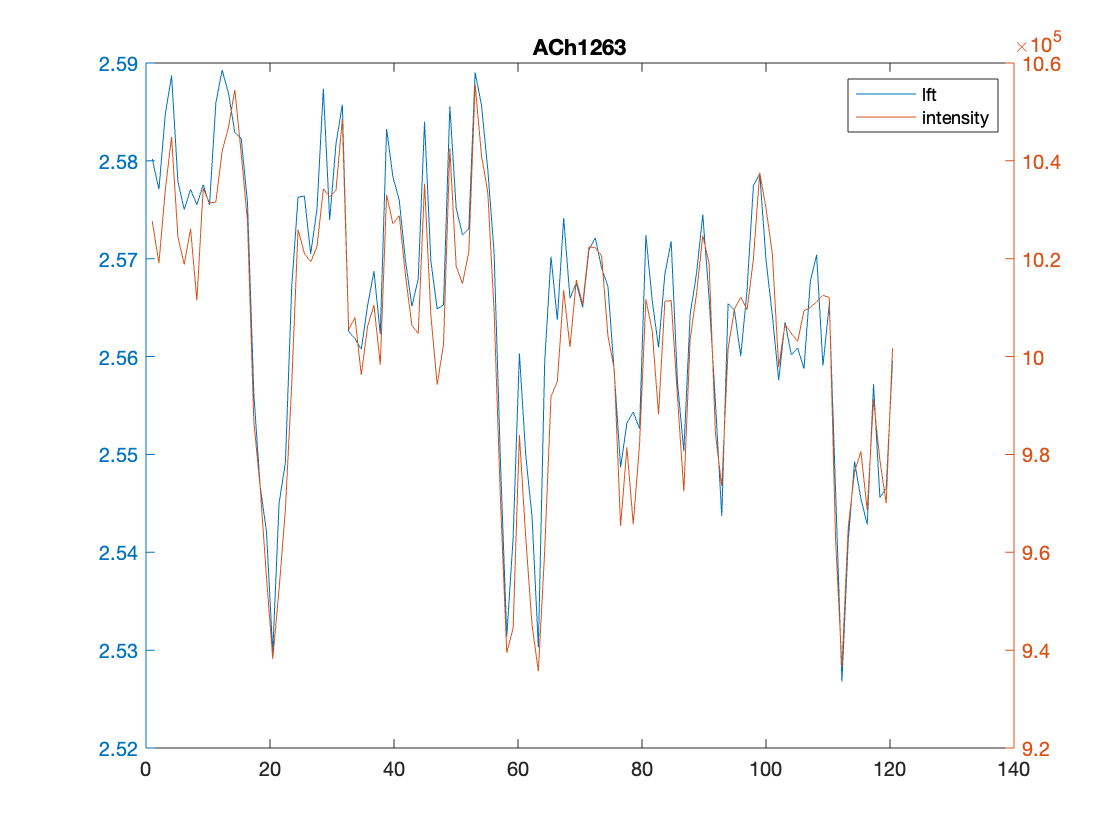

% figure
% yyaxis left
% plot(ACh1263_time, ACh1263_tau_empTrunc)
% yyaxis right
% plot(ACh1263_time, ACh1263_photoncount)
% title('ACh1263')
% legend('lft','intensity')

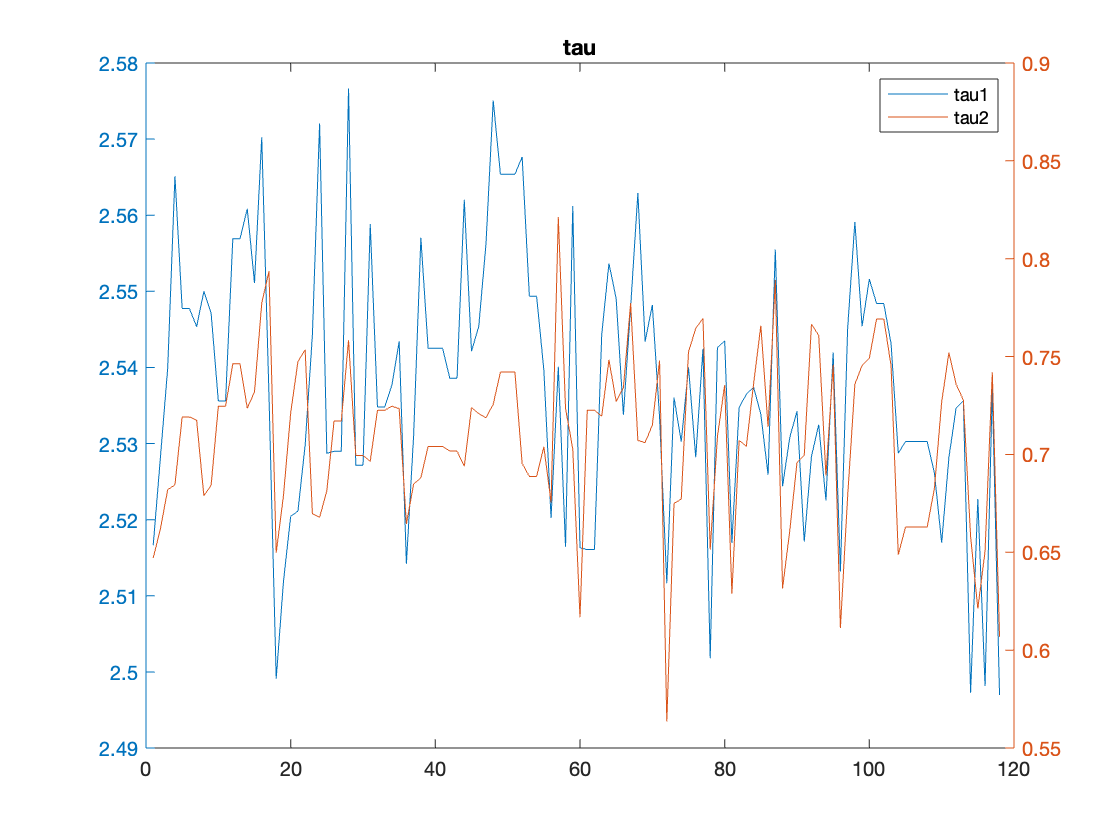

% 
% figure
% yyaxis left
% plot(ACh1263_beta2)
% yyaxis right
% plot(ACh1263_beta4)
% title('tau')
% legend('tau1','tau2')

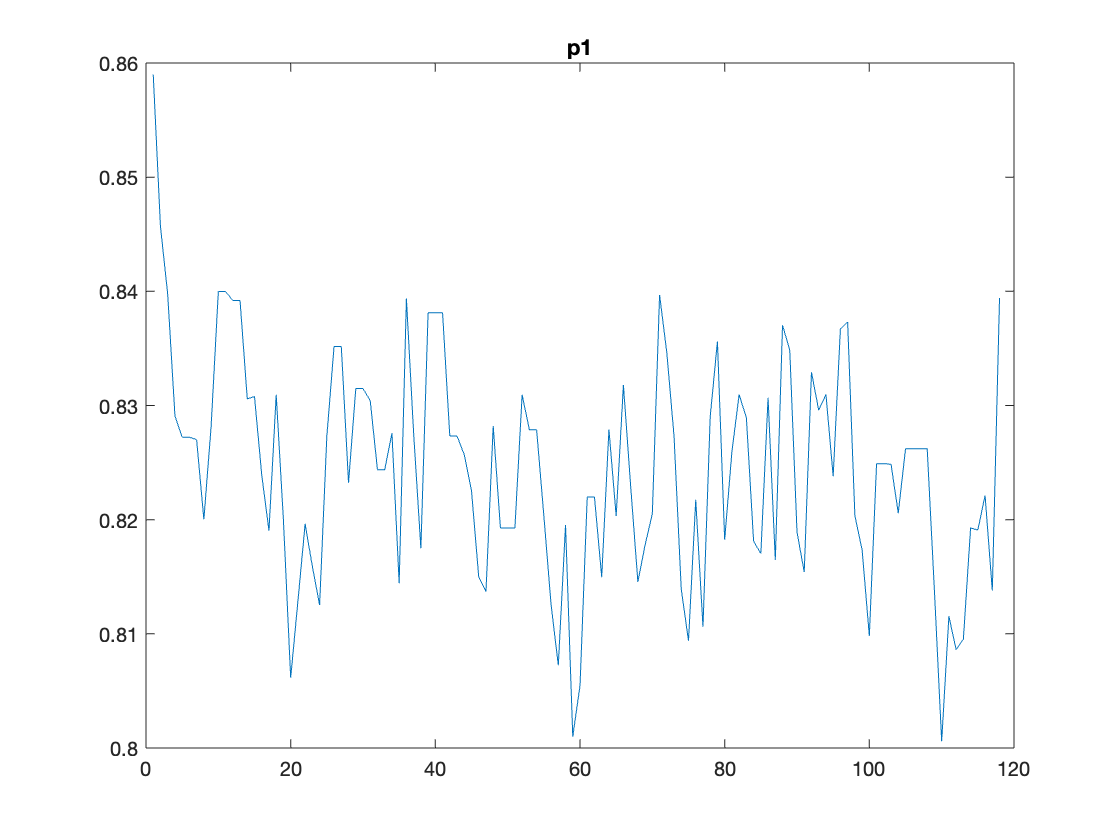

% 
% figure
% plot(ACh1263_p1)
% title('p1')

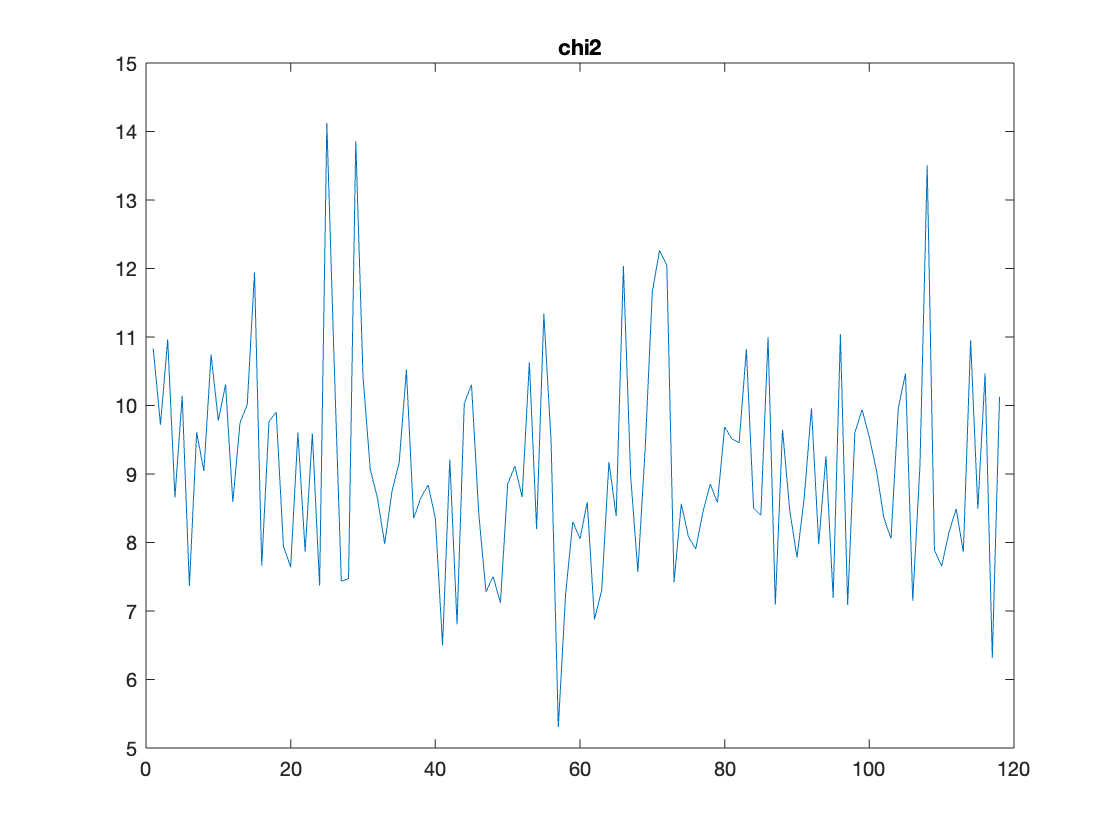

% 
% figure
% plot(ACh1263_chi2)
% title('chi2')

% 
% mean(ACh1263_beta2)

ans = 2.5378

% mean(ACh1263_beta4)

ans = 0.7087

% mean(ACh1263_p1)

ans = 0.8244

% mean(ACh1263_beta5)

ans = 1.9383

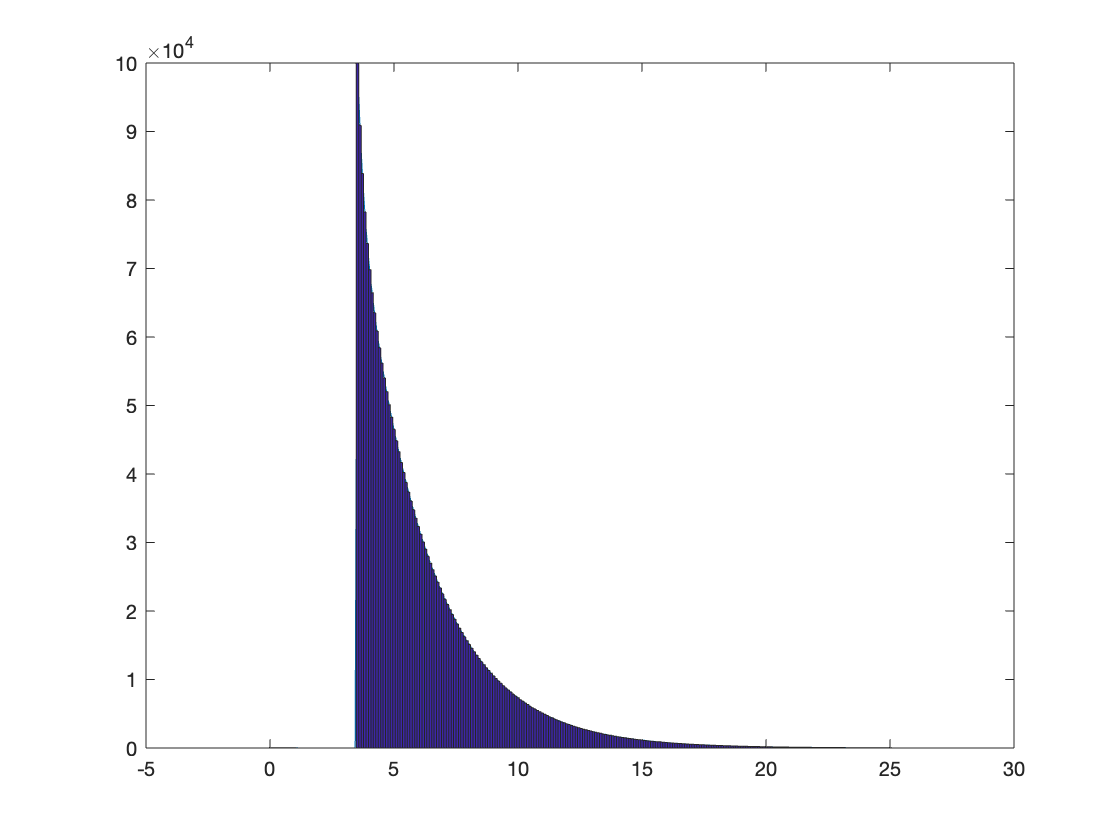

     2311929



SimulationName='simulation_FLP_012022';
mkdir(SimulationName); % make directory that contains all the simulated data


tau1=2.706;
p1=0.8;
tau2=0.2613;
p2=0.2; % copied from /Users/pingchuanma/Library/CloudStorage/Box-Box/ChenLab/Pingchuan/Ach FLIM Manuscript Preparation/Figure 2-Simulation/Simulation_instructions'
PopulationName='Simulation_012022_FLP_population';

cd(SimulationName);
GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName);

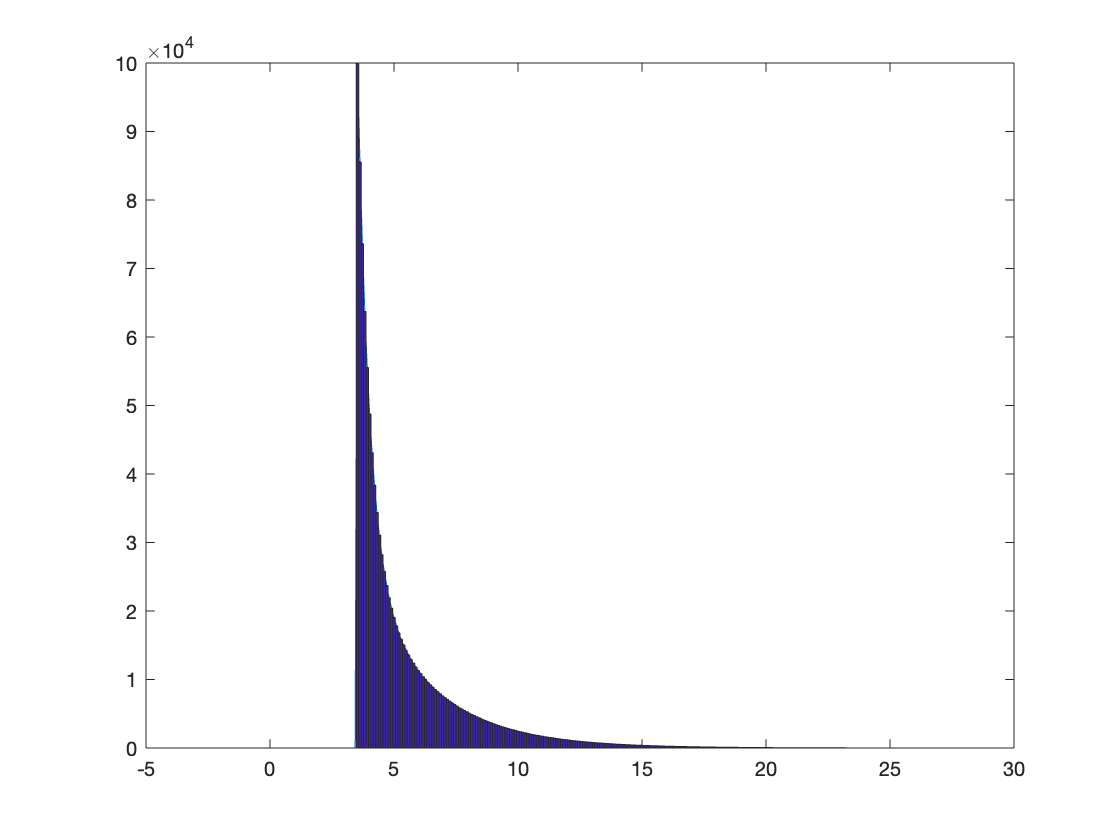

     1151666




% autofluorescence

tau1=2.7055;
p1=0.2692;
tau2=0.4798;
p2=0.7308;
PopulationName='Simulation_012022_autofluo_population';

GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName);

To simulate, one missing parameter is the gaussian width from fitting, which needs to be re-collected.

It turns out that the gaussian width from autofluorescence fitting and ACh 3.0 fluorescence fitting is different.

Another question is there are two ways of adding autofluorescence: 1) from fitting and simulation; 2) from empirical shape of the autofluorescence. For the 1st one, I've collected the tau1, tau2, p1, p2 and the corresponding width from gaussian fitting. For the 2nd one, I need to recollect the empirical shape of the histograms.

% PM13_lifetime_histograms_normolized=[];
% 
% for i=1:size(PM13_time,1)
%     PM13_lifetime_histograms_normolized(:,i)=PM13_lifetime_histograms(:,i)/max(PM13_lifetime_histograms(:,i));
% end
% 
% PM13_lifetimes=zeros(256,1);
% 
% for i=1:256
%     PM13_lifetimes(i)=mean(PM13_lifetime_histograms_normolized(i,:));
% end

% KQ17_lifetime_histograms_normolized=[];
% 
% for i=1:size(KQ17_time,1)
%     KQ17_lifetime_histograms_normolized(:,i)=KQ17_lifetime_histograms(:,i)/max(KQ17_lifetime_histograms(:,i));
% end
% 
% KQ17_lifetimes=zeros(256,1);
% 
% for i=1:256
%     KQ17_lifetimes(i)=mean(KQ17_lifetime_histograms_normolized(i,:));
% end


% ACh1263_lifetime_histograms_normolized=[];
% 
% for i=1:size(ACh1263_time,1)
%     ACh1263_lifetime_histograms_normolized(:,i)=ACh1263_lifetime_histograms(:,i)/max(ACh1263_lifetime_histograms(:,i));
% end
% 
% ACh1263_lifetimes=zeros(256,1);
% 
% for i=1:256
%     ACh1263_lifetimes(i)=mean(ACh1263_lifetime_histograms_normolized(i,:));
% end

The next issue is to decide 'prf', which here is the gaussian distribution function to convolute the signal. The parameters needed is the mean and the sigma. I decide the mean based on one prf file I collected before. The mean corresponds to the peak channel of the prf (which is 37, 37*(25/256)=3.6133 ns). Then the question is what's the relationship between the sigma and beta6, which is called the Gaussian width.

width=mean(ACh1263_beta6)

width = 0.1554

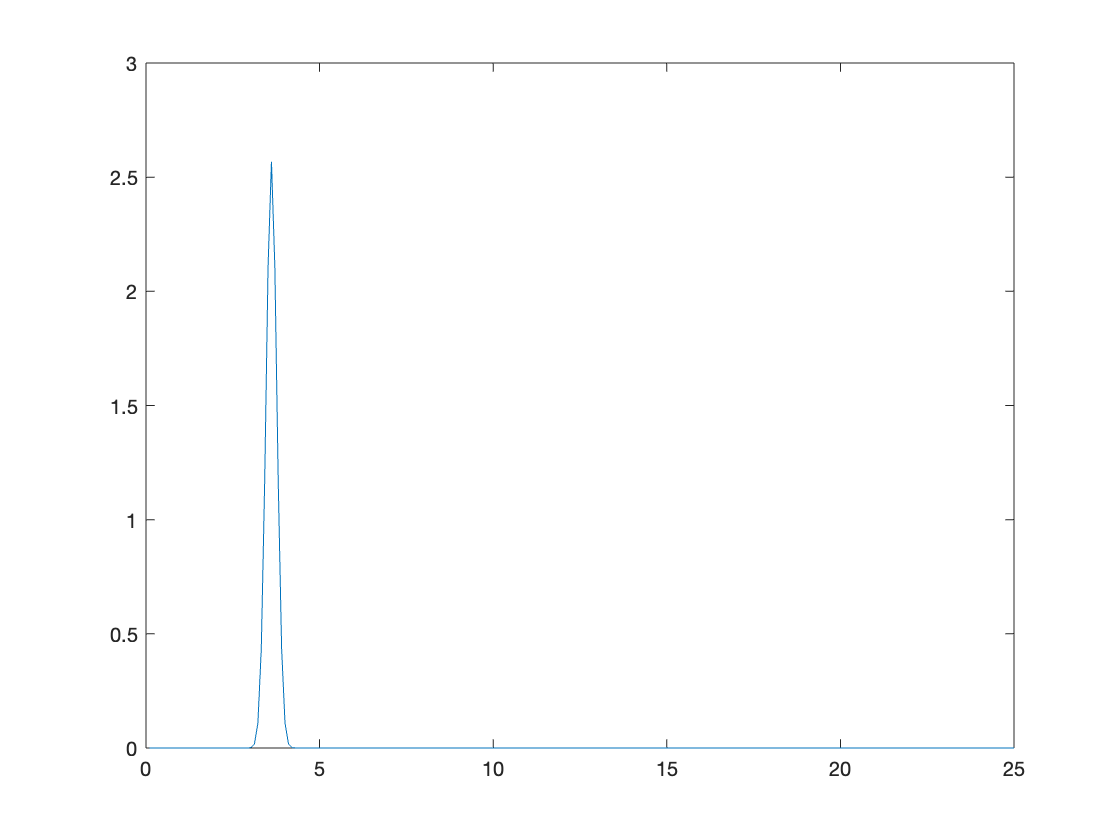

miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
figure
plot(x,Gaussian_y)

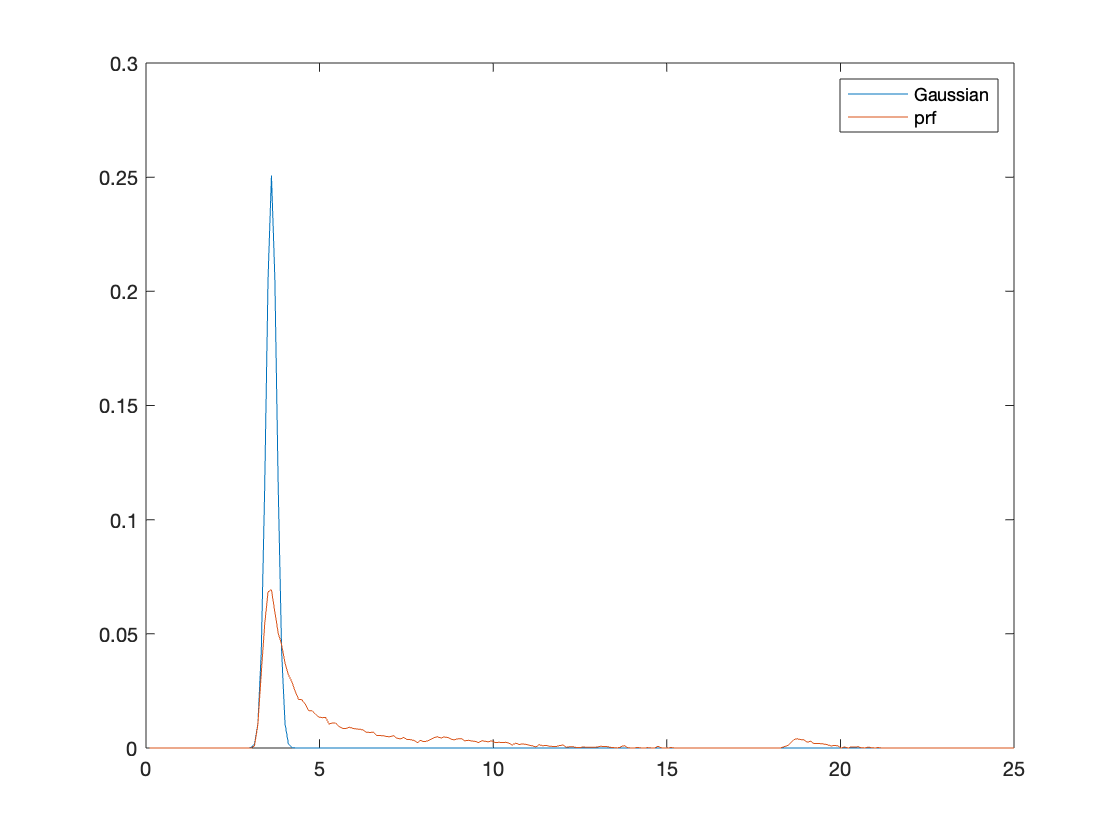


Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
plot(x,Gaussian_y)
hold on
plot(x,prf)
legend('Gaussian','prf')


Gaussian_y=Gaussian_y';

Relationship between p1 and average tau:

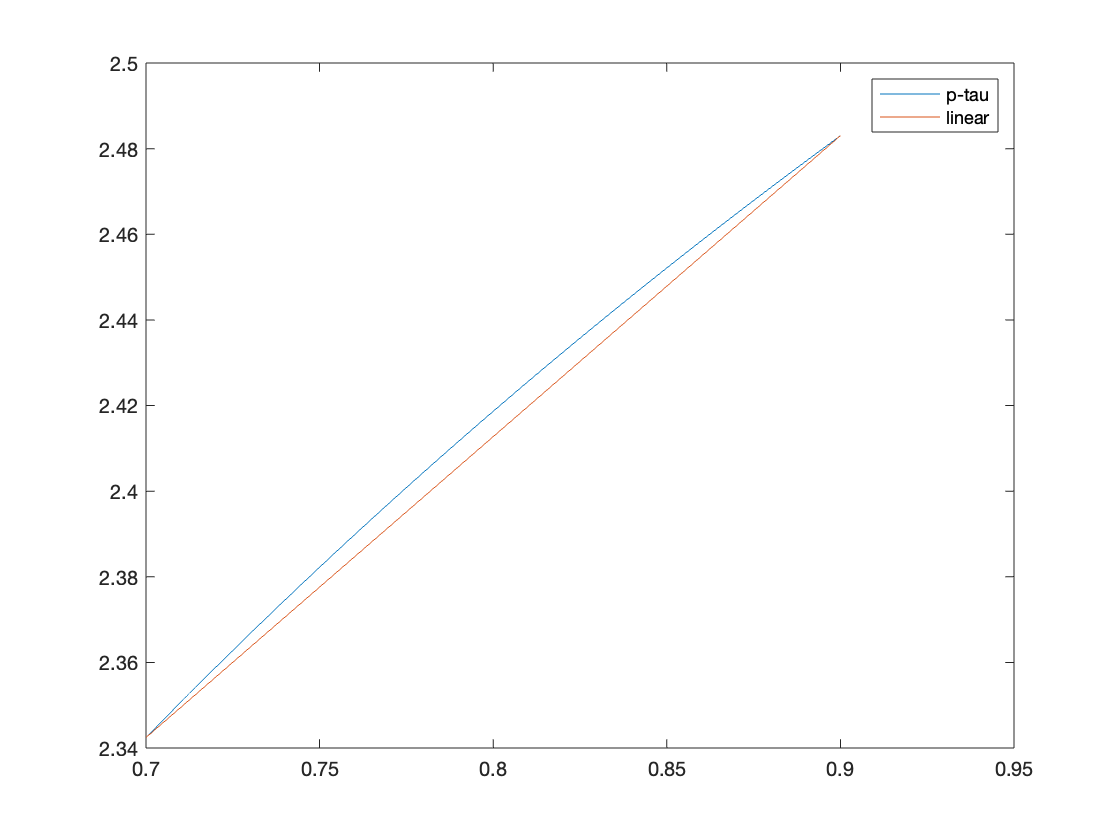

tau1=2.5381;
tau2=0.7096;

p=0.7:0.0002:0.9;
mean_tau=zeros(1,1001);

for i=1:1001
    mean_tau(i)=(tau1*tau1*p(i)+tau2*tau2*(1-p(i)))/(tau1*p(i)+tau2*(1-p(i)));
end

line_x=[0.7 0.9];
line_y=[mean_tau(1) mean_tau(1001)];

figure
plot(p,mean_tau)
hold on
plot(line_x,line_y)
legend('p-tau','linear')

% SS=200000;
% AF=200000;
% PopulationName='Simulation_122221_FLP_population.mat';
% autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
% global Gaussian_y autofluo prf
% 
% mkdir(num2str(SS))

% for i=1:50
%     samplename=[num2str(SS),'/',num2str(i),'_noauto.mat'];
%     FLIMsim256_FLP(SS,AF,PopulationName,samplename)
% end




AF=200000;
PopulationName='Simulation_012022_autofluo_population';
% autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
global Gaussian_y prf

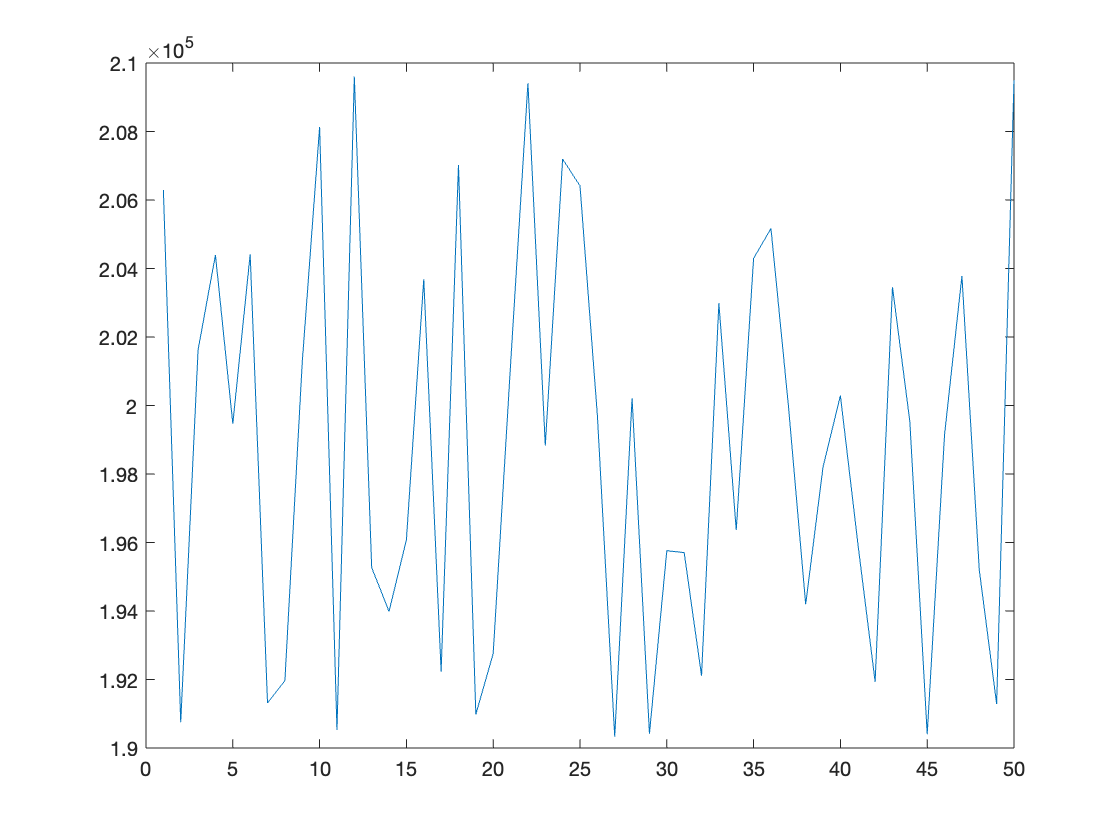

SS_all=zeros(1,50);

mkdir([num2str(AF),'_AF'])
for i=1:50
    SS=randi(20000)+190000; % 5% of fluctuation
    SS_all(i)=SS;
    samplename=[num2str(AF),'_AF/',num2str(i),'_auto.mat'];
    FLIMsim256_FLP(SS,AF,PopulationName,samplename)
end

figure
plot(SS_all)

SS=300000;
AF=200000;
PopulationName='Simulation_122221_FLP_population.mat';
autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
global Gaussian_y autofluo prf

mkdir(num2str(SS))
for i=1:50
    samplename=[num2str(SS),'/',num2str(i),'_noauto.mat'];
    FLIMsim256_FLP(SS,AF,PopulationName,samplename)
end

SS=400000;
AF=200000;
PopulationName='Simulation_122221_FLP_population.mat';
autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
global Gaussian_y autofluo prf

mkdir(num2str(SS))
for i=1:50
    samplename=[num2str(SS),'/',num2str(i),'_noauto.mat'];
    FLIMsim256_FLP(SS,AF,PopulationName,samplename)
end


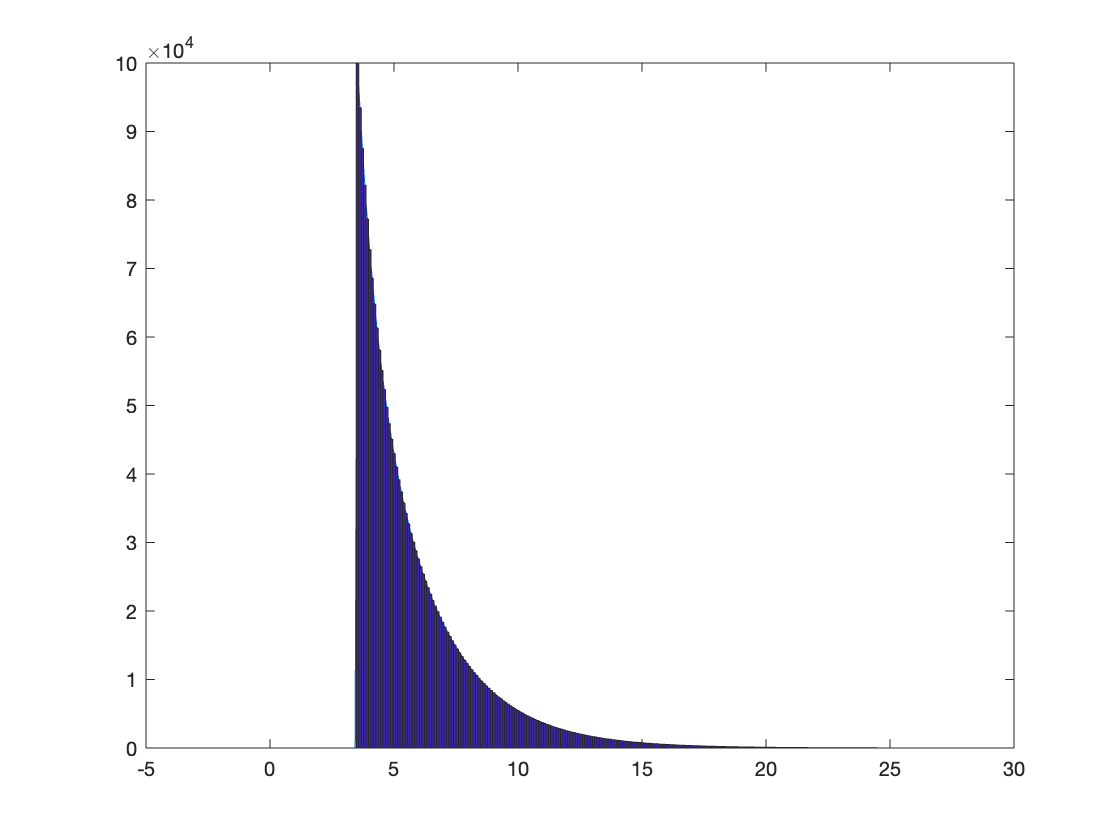

     2079696



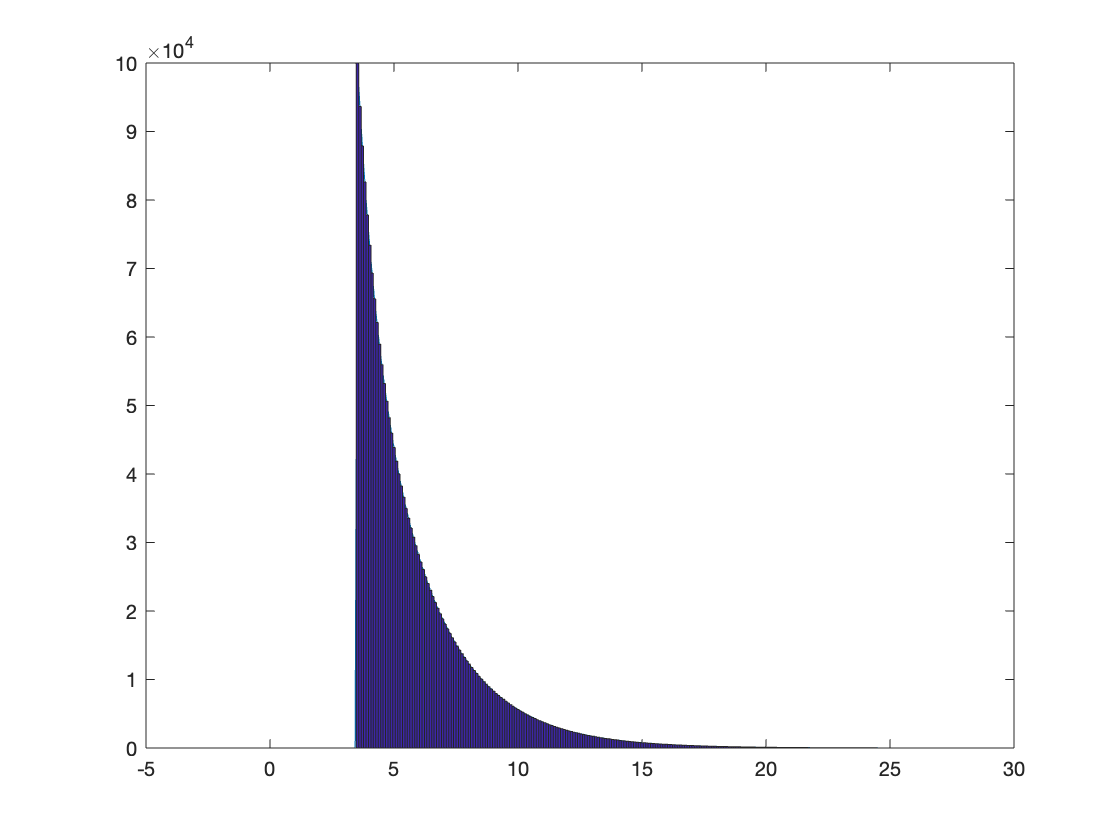

     2116966



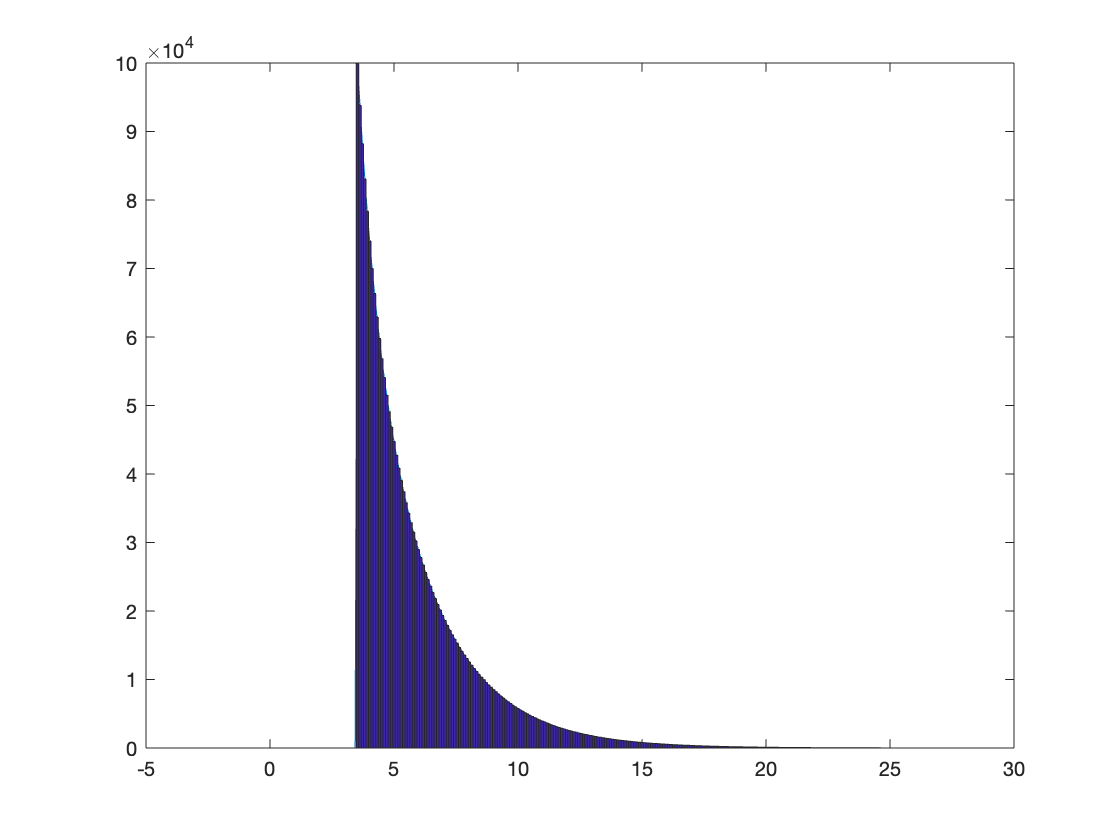

     2154252



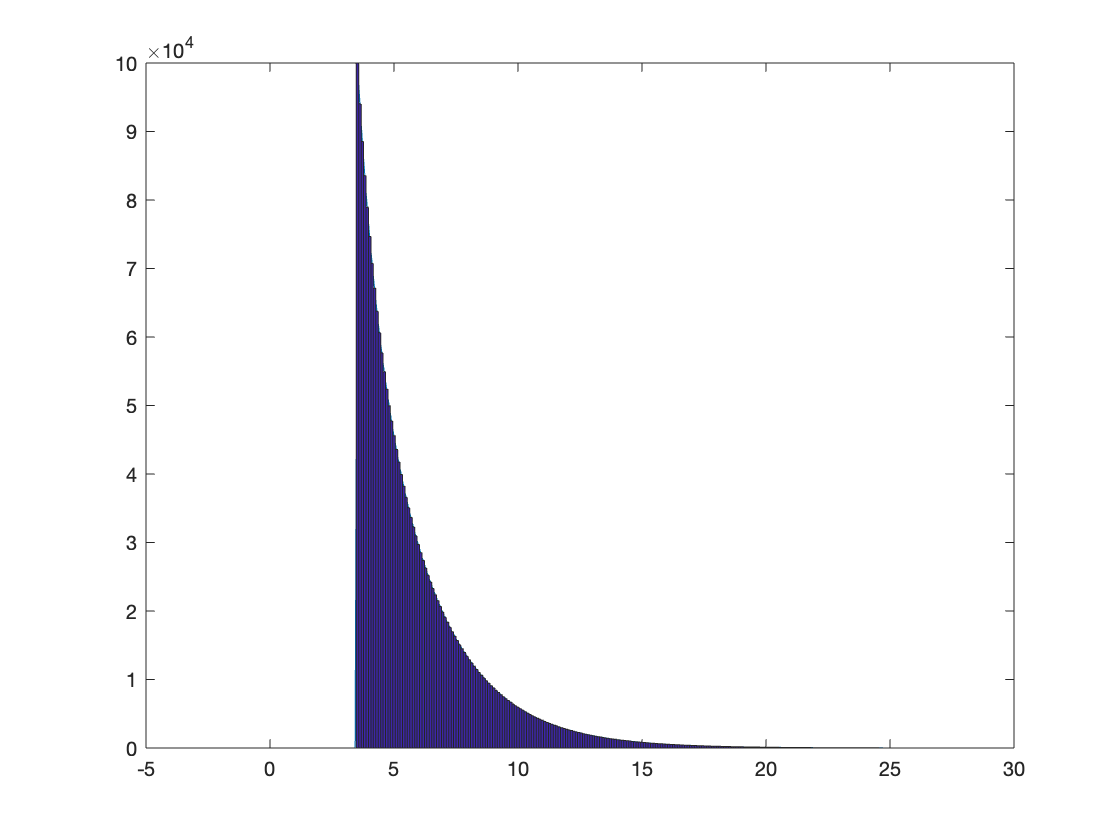

     2191528



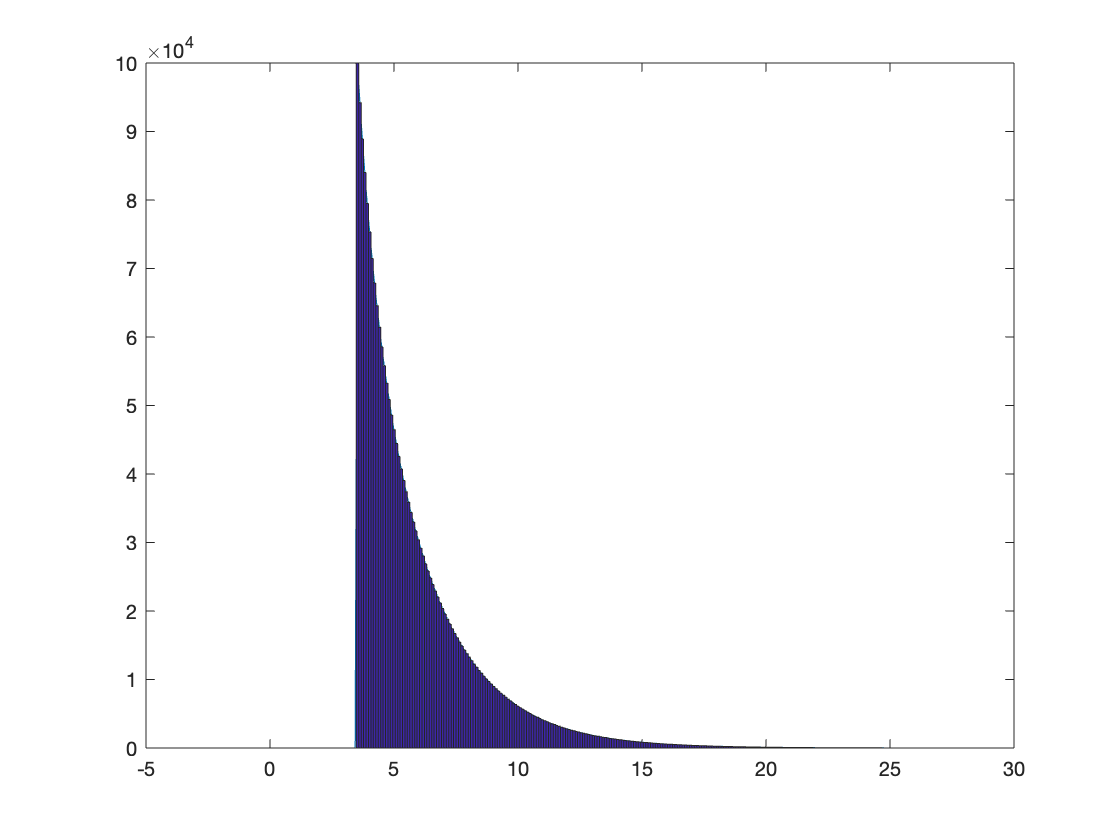

     2228820



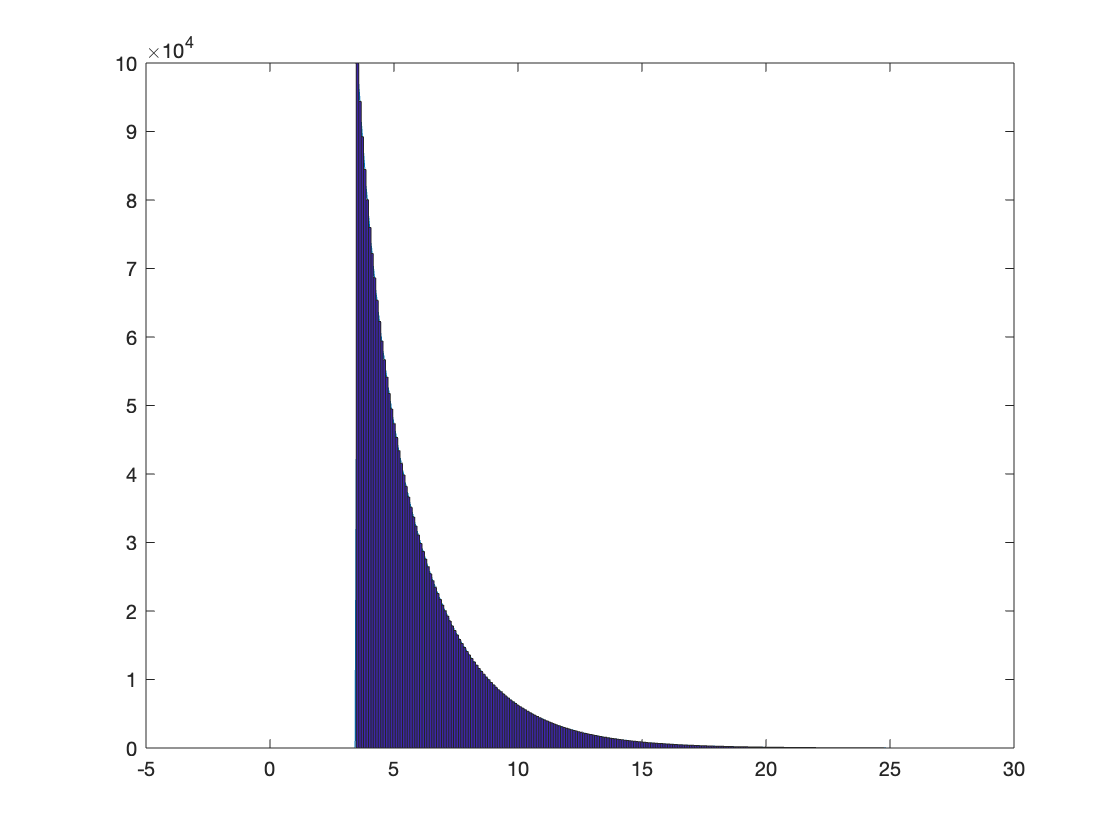

     2266100



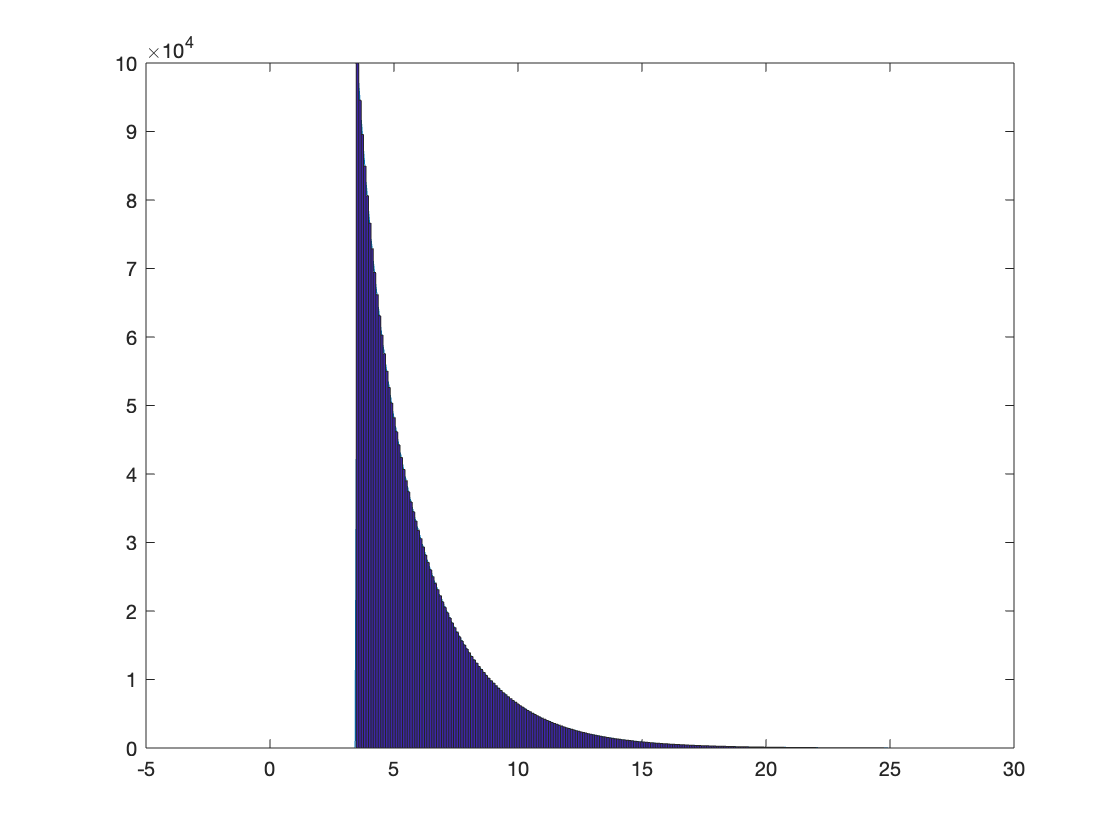

     2303377



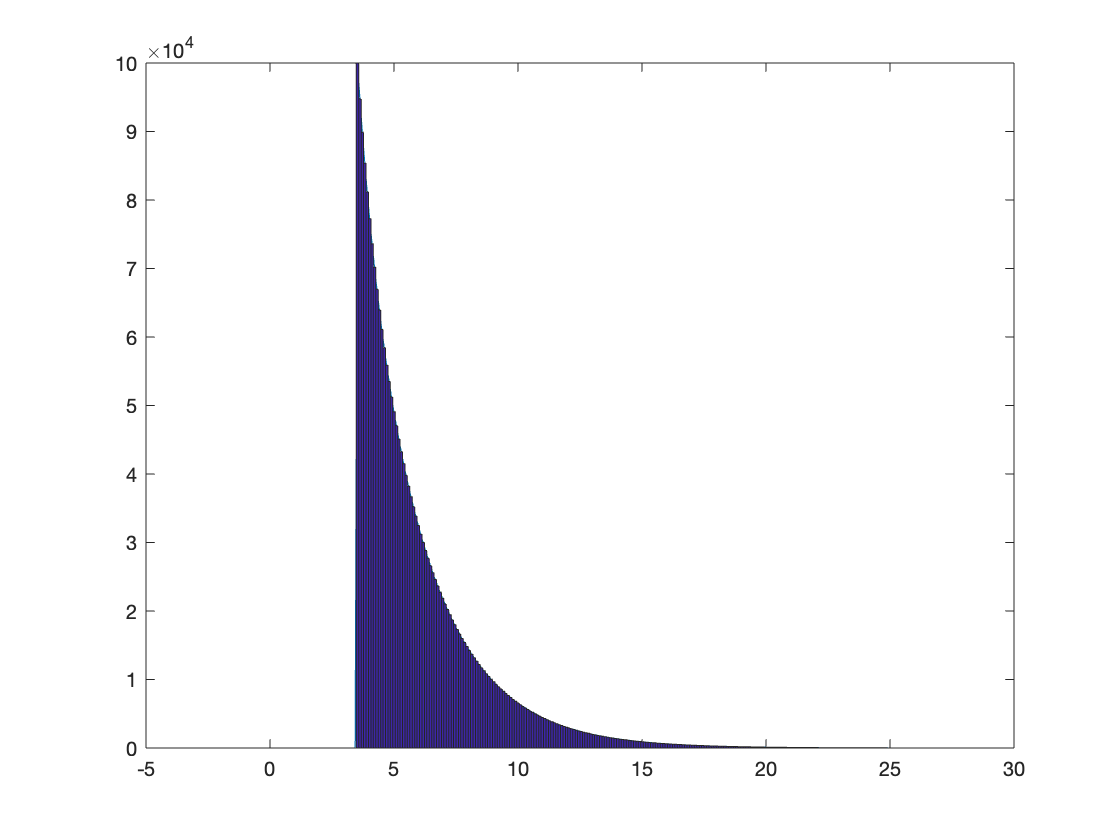

     2340660



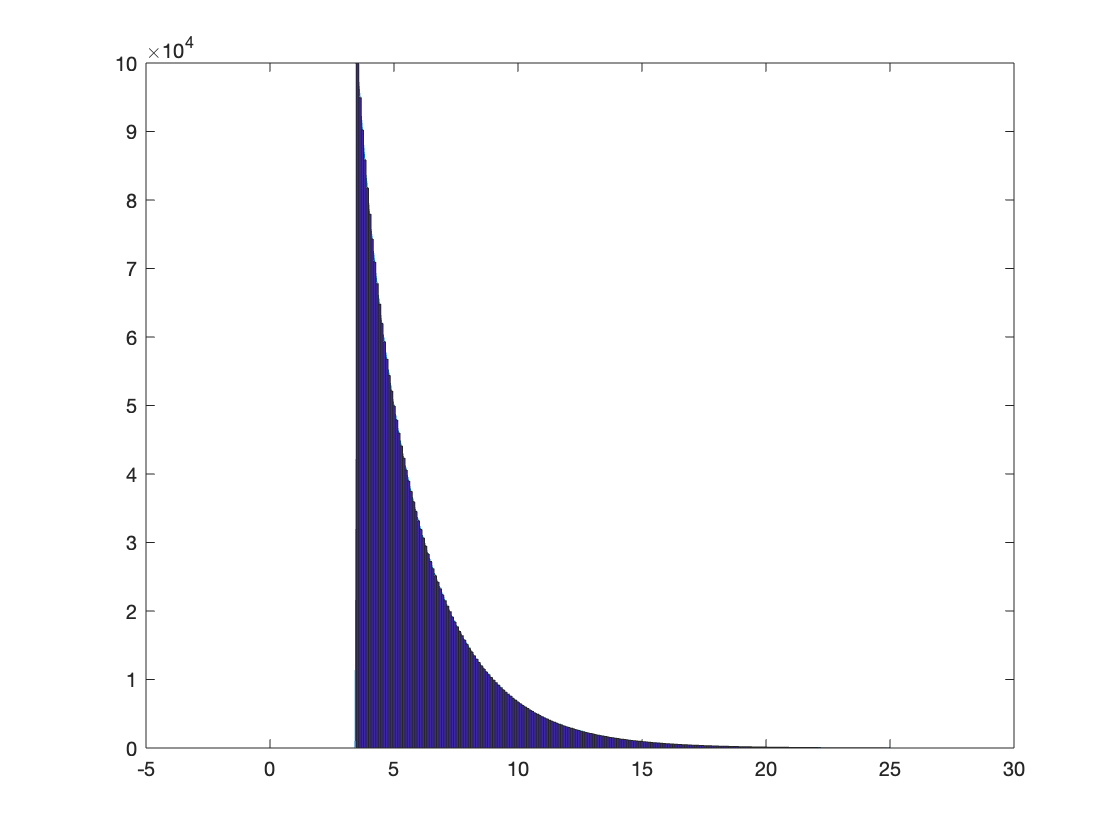

     2377937



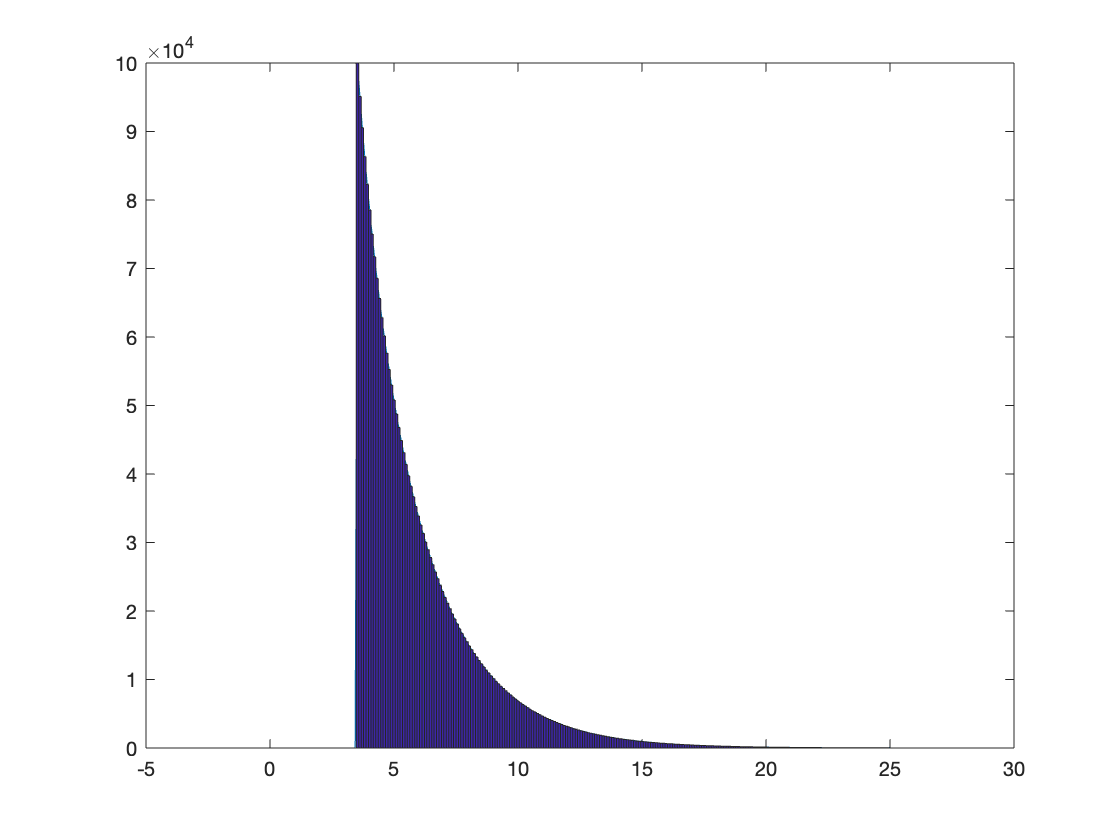

     2415221



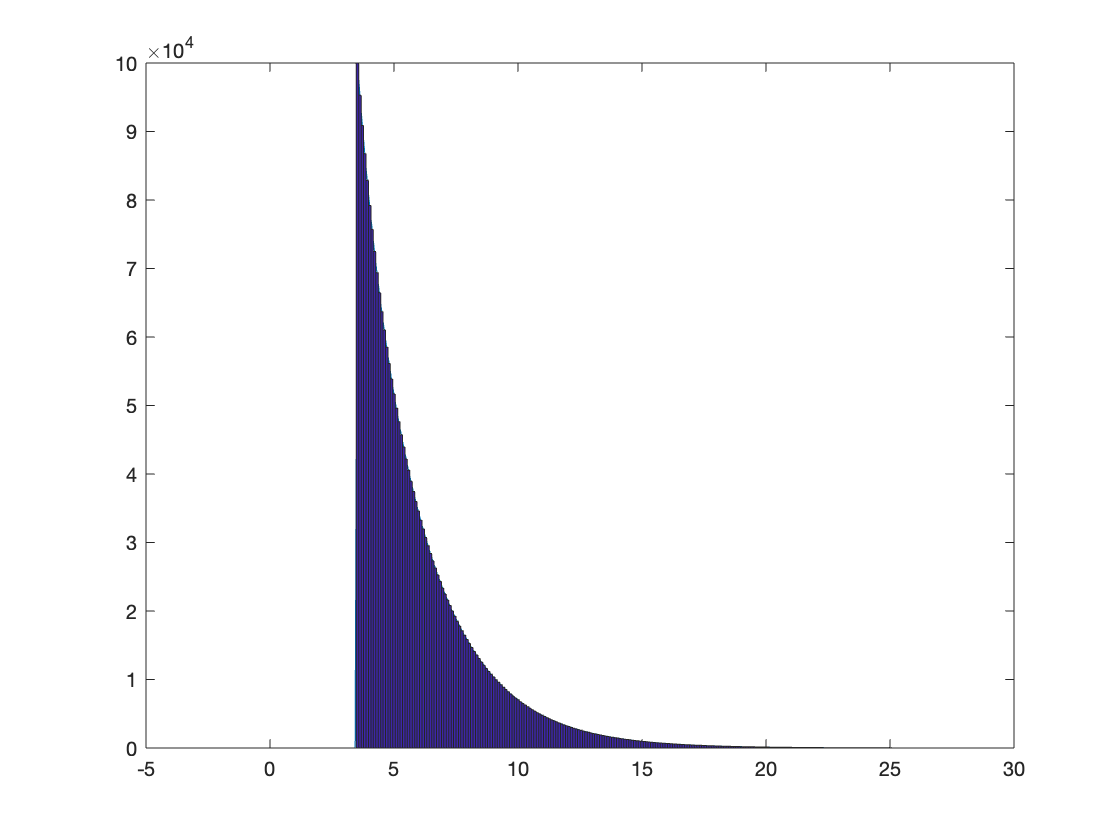

     2452509



p1_samples=0.7:0.02:0.9;
tau1=2.706;
SS_samples=[200000 300000 400000 500000 600000 700000 800000 900000 1000000];
% autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
global Gaussian_y prf

for i=1:11
    p1=p1_samples(i);
    p2=1-p1;
    PopulationName=['Simulation_012022_FLP_population_',num2str(p1),'.mat'];
    GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName);
    for j=1:9
        SS=SS_samples(j);
        mkdir([num2str(SS),'_',num2str(p1)])
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            FLIMsim256_FLP(SS,AF,PopulationName,samplename)
        end
    end
end

p1_samples=0.7:0.02:0.9;
SS_samples=[200000 300000 400000 500000 600000 700000 800000 900000 1000000];

for i=1:11
    p1=p1_samples(i);
 

    for j=1:9
        SS=SS_samples(j);
%         mkdir([num2str(SS),'_',num2str(p1),'_auto'])
        
        tau_avg=[];
        tau_avgTrunc=[];
        tau_empTrunc=[];
        photoncount=[];
        p1_sim=[];
        chi2=[];
        beta2=[];
        beta4=[];
        beta5=[];
        beta6=[];
        lifetime_histograms=[];
        
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n';
            AFname=['200000_AF/',num2str(k),'_auto.mat'];
            load(AFname);
            n_auto=n';
            spc.lifetimes{1}=n_ACh+n_auto;
            
            spc_fitexp2gaussGY(ch);
%             spc_adjustTauOffset(1);
            
            
            photoncount(k)=sum(spc.lifetimes{1});
            p1_sim(k)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3);
            tau_avg(k)=spc.fits{ch}.avgTau; % mean Tau calculated from fit
            tau_avgTrunc(k)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k)=spc.fits{ch}.EmpTauTrunc;
            chi2(k)=spc.fits{ch}.redchisq;
            beta2(k)=spc.fits{ch}.beta2;
            beta4(k)=spc.fits{ch}.beta4;
            beta5(k)=spc.fits{ch}.beta5;
            beta6(k)=spc.fits{ch}.beta6;
            lifetime_histograms=[lifetime_histograms spc.lifetimes{1}];
            
        end
        
        photoncount=transpose(photoncount);
        tau_avg=transpose(tau_avg);
        tau_avgTrunc=transpose(tau_avgTrunc);
        tau_empTrunc=transpose(tau_empTrunc);
        p1_sim=transpose(p1_sim);
        chi2=transpose(chi2);
        beta2=transpose(beta2);
        beta4=transpose(beta4);
        beta5=transpose(beta5);
        beta6=transpose(beta6);
        
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        save(result_name,'photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1_sim','chi2','beta2','beta4','beta5','beta6','lifetime_histograms')
    end
end


p1_samples=0.7:0.02:0.9;
SS_samples=[200000 300000 400000 500000 600000 700000 800000 900000 1000000];

for i=1:11
    p1=p1_samples(i);
    eval(['tau_empTrunc_',num2str(i),'=[];'])
    for j=1:9
        SS=SS_samples(j);
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(i),'=[tau_empTrunc_',num2str(i),' tau_empTrunc];'])
    end
end

for j=1:9
    SS=SS_samples(j);
    eval(['tau_empTrunc_',num2str(SS),'=[];'])
    
    for i=1:11
        p1=p1_samples(i);
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(SS),'=[tau_empTrunc_',num2str(SS),' tau_empTrunc];'])
    end
end



calculation of the mean and std of each condition of simulation

std_all=[];
mean_all=[];

for i=1:9
    SS=SS_samples(i);
    eval(['this_samplesize=tau_empTrunc_',num2str(SS),';'])
    std_all=[std_all;std(this_samplesize)];
    mean_all=[mean_all;mean(this_samplesize)];
end



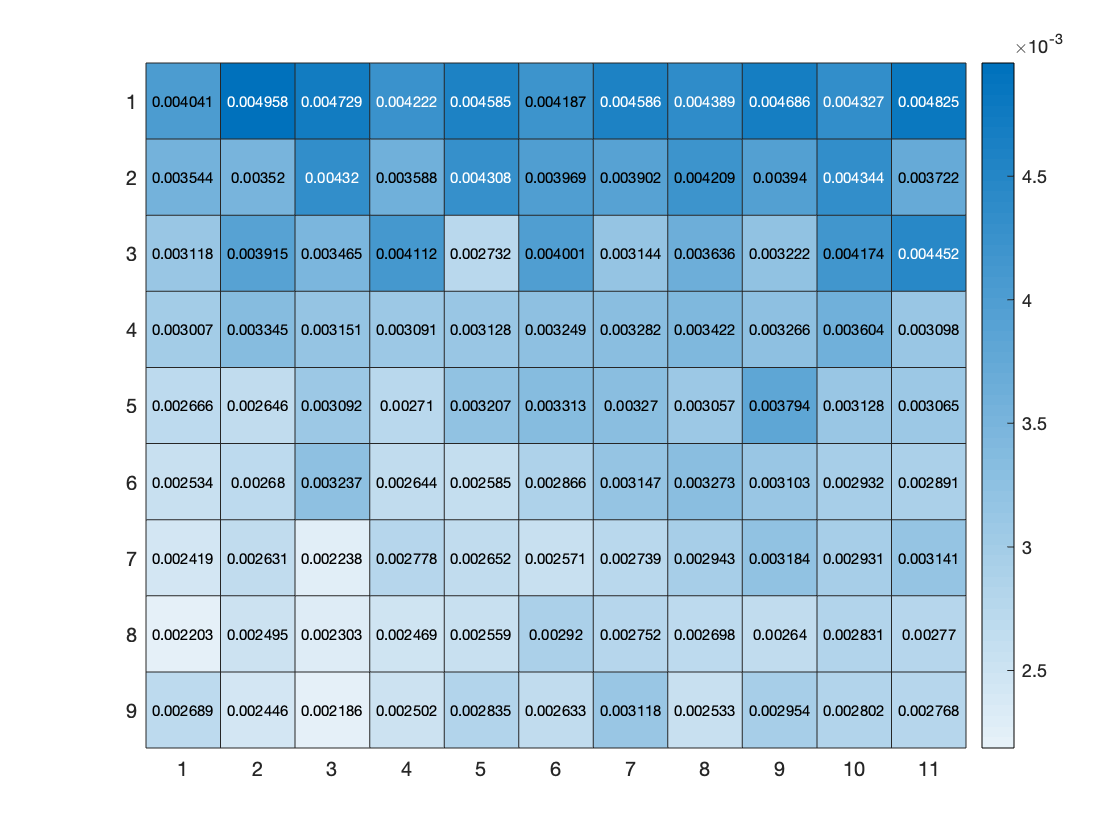

ans =   HeatmapChart with properties:

        XData: {11×1 cell}
        YData: {9×1 cell}
    ColorData: [9×11 double]

  Show all properties


figure
heatmap(std_all)

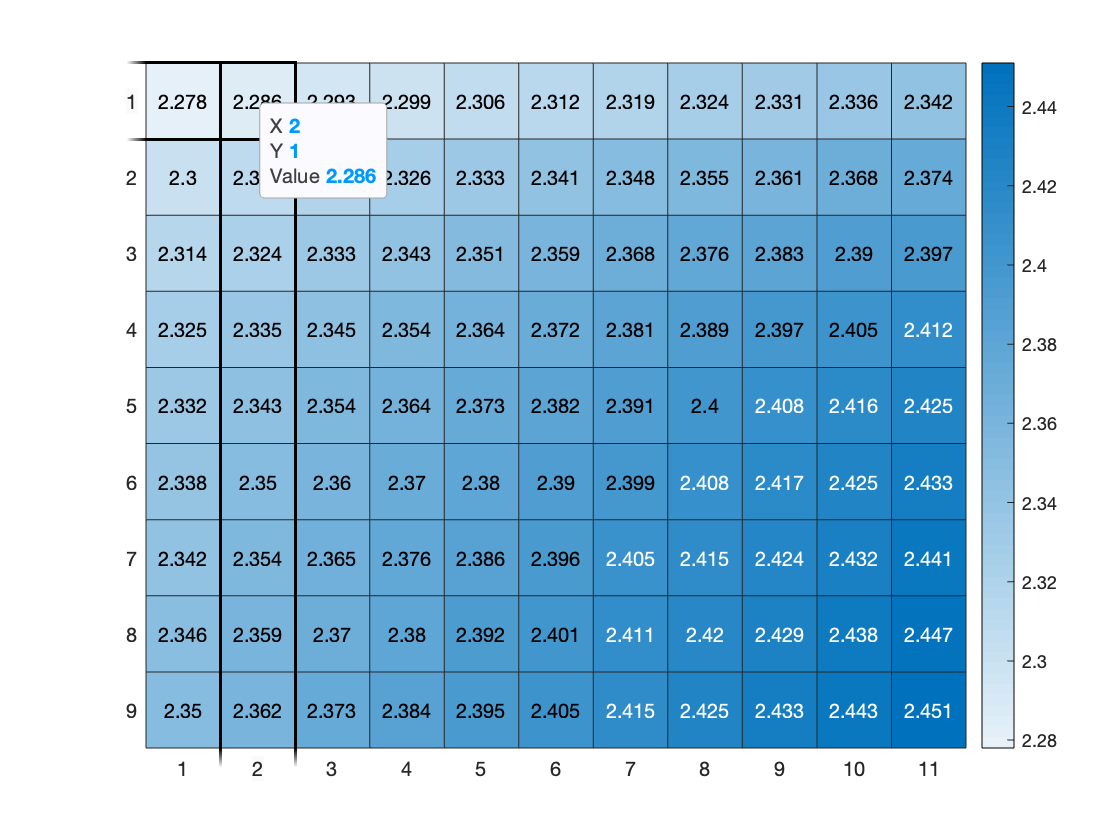

ans =   HeatmapChart with properties:

        XData: {11×1 cell}
        YData: {9×1 cell}
    ColorData: [9×11 double]

  Show all properties



figure
heatmap(mean_all)

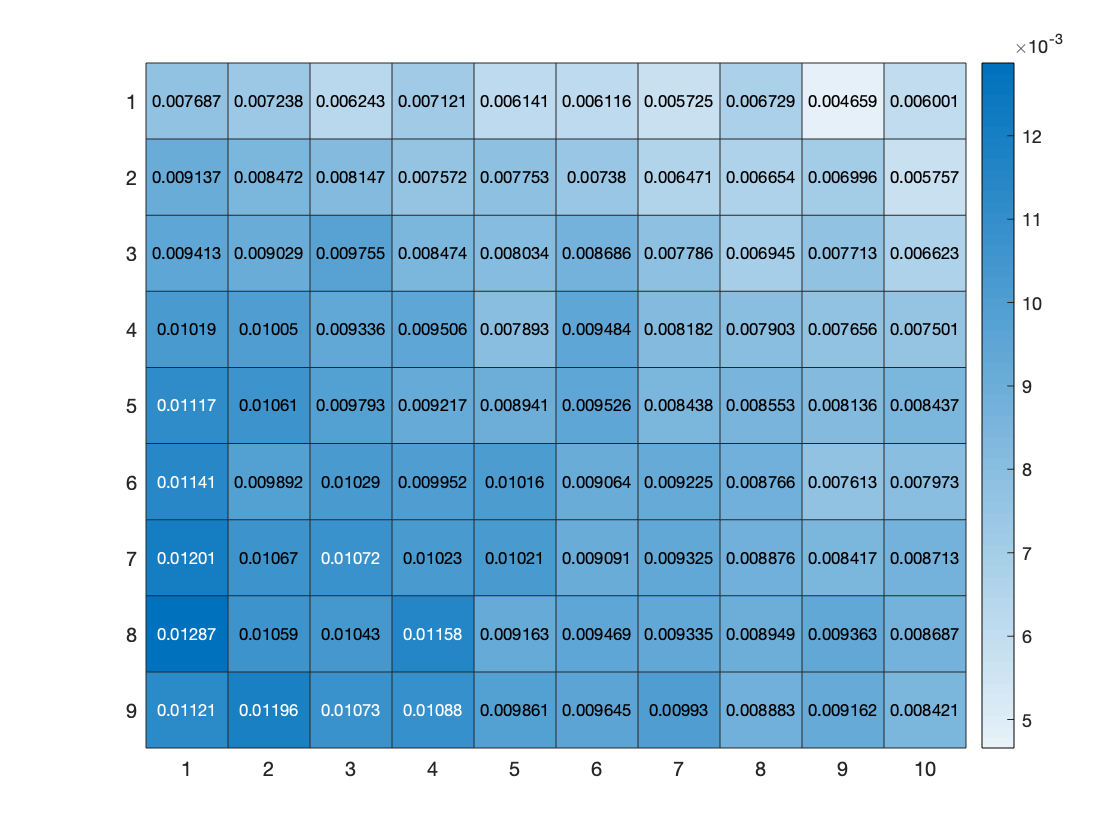

ans =   HeatmapChart with properties:

        XData: {10×1 cell}
        YData: {9×1 cell}
    ColorData: [9×10 double]

  Show all properties


mean_all_diff=zeros(9,10);
for i=1:10
    mean_all_diff(:,i)=mean_all(:,i+1)-mean_all(:,i);
end

figure
heatmap(mean_all_diff)

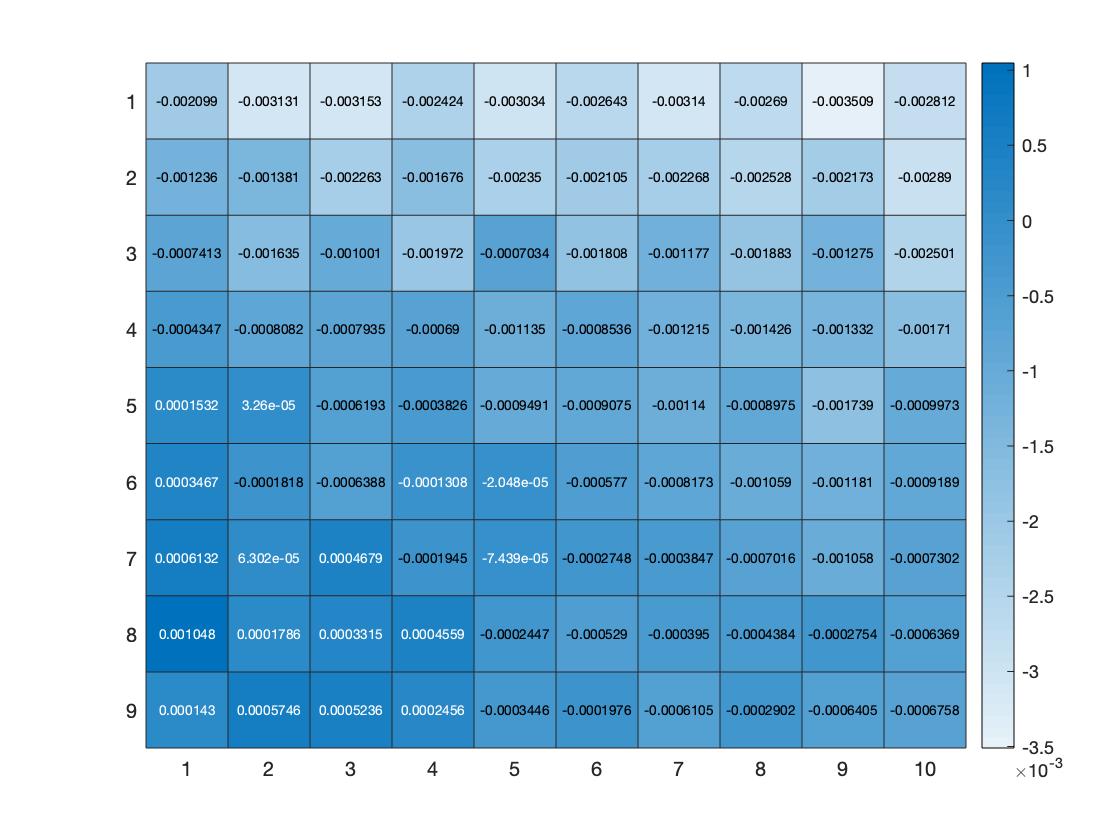

ans =   HeatmapChart with properties:

        XData: {10×1 cell}
        YData: {9×1 cell}
    ColorData: [9×10 double]

  Show all properties



diff=mean_all_diff/3.96-std_all(:,1:10);
figure
heatmap(diff)

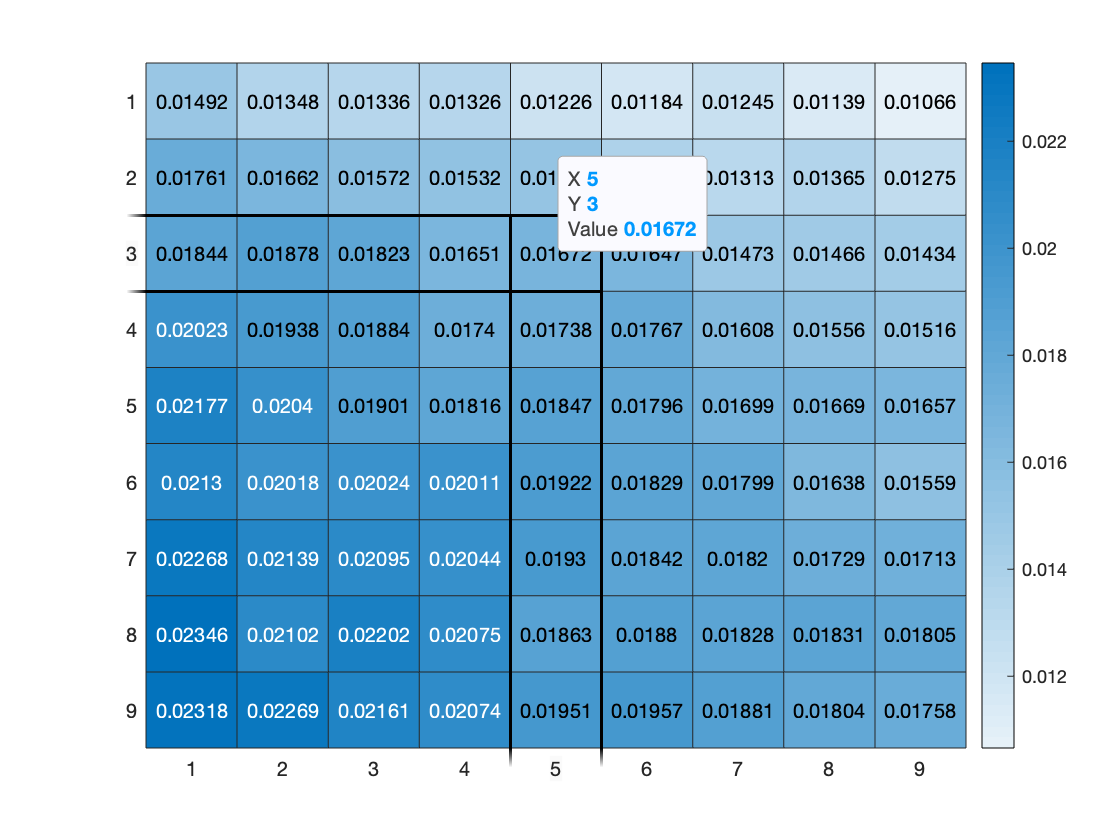

ans =   HeatmapChart with properties:

        XData: {9×1 cell}
        YData: {9×1 cell}
    ColorData: [9×9 double]

  Show all properties


mean_all_diff=zeros(9,9);

for i=1:9
    mean_all_diff(:,i)=mean_all(:,i+2)-mean_all(:,i);
end

figure
heatmap(mean_all_diff)

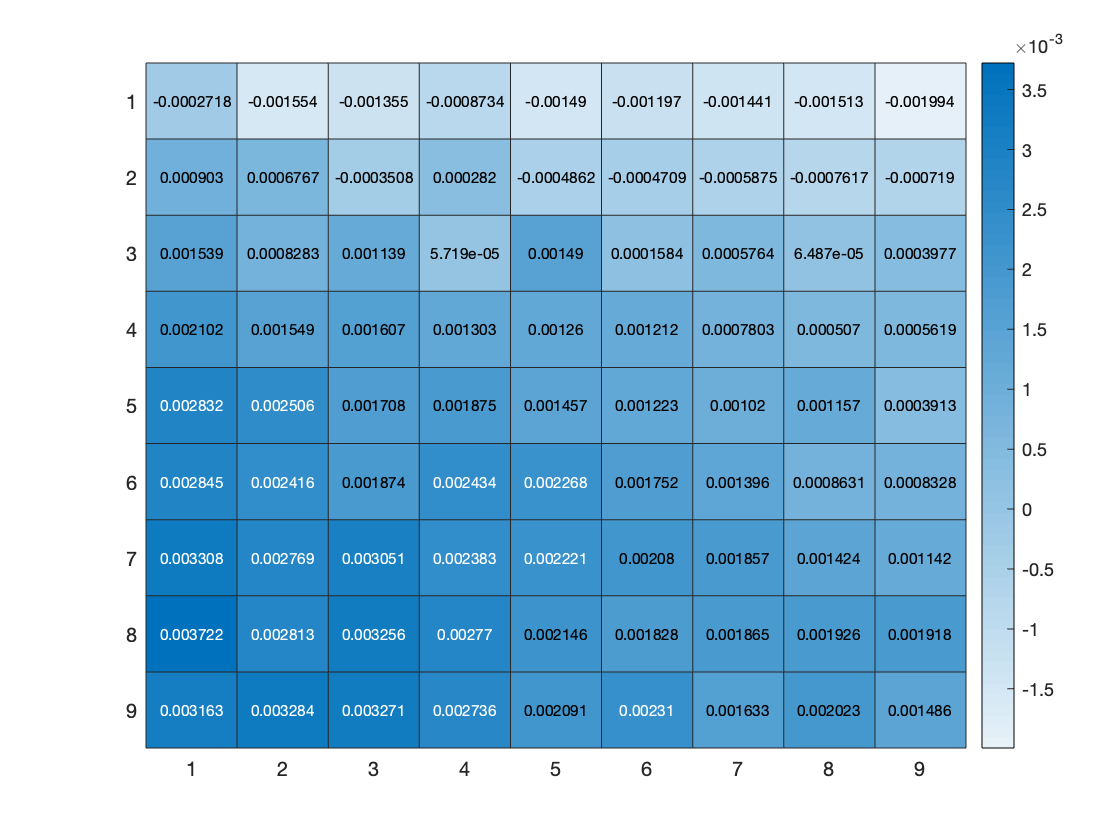

ans =   HeatmapChart with properties:

        XData: {9×1 cell}
        YData: {9×1 cell}
    ColorData: [9×9 double]

  Show all properties



diff=mean_all_diff/3.96-std_all(:,1:9);
figure
heatmap(diff)

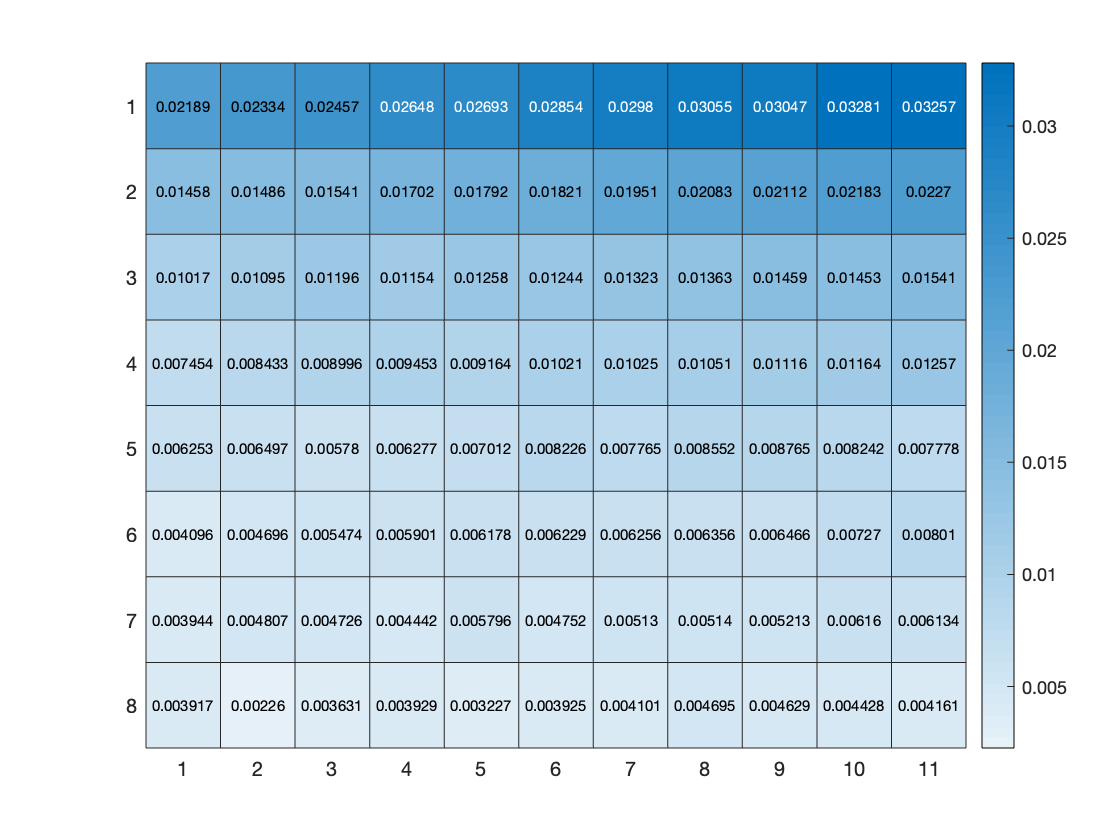

ans =   HeatmapChart with properties:

        XData: {11×1 cell}
        YData: {8×1 cell}
    ColorData: [8×11 double]

  Show all properties


mean_all_diff2=zeros(8,11);
for i=1:8
    mean_all_diff2(i,:)=mean_all(i+1,:)-mean_all(i,:);
end

figure
heatmap(mean_all_diff2)

2.8*sqrt(2)*sigma/sqrt(n) = signal

n=1?

assume signal=